# Experiment with biLSTMpathToEEG model(3 channels)

## Load data

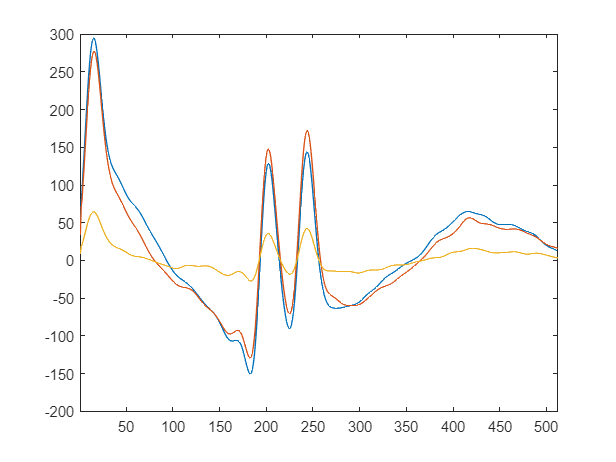

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate |    numBlocks | numHiddenUni-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | ts           |
|===================================================================================================================================|
|    1 | Best   |    0.086222 |      379.46 |    0.086222 |    0.086222 |          110 |     0.046967 |            2 |          123 |
|    2 | Best   |     0.08361 |      735.42 |     0.08361 |     0.08361 |           22 |     0.027385 |            2 |           22 |
|    3 | Best   |    0.078624 |      129.08 |    0.078624 |    0.078624 |           98 |   0.00011554 |            1 |           50 |
|    4 | Best   |    0.078424 |      1071.8 |    0.078424 |   

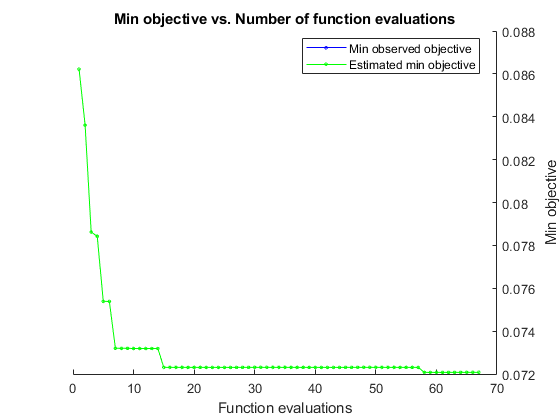


__________________________________________________________
Optimization completed.
MaxTime of 14400 seconds reached.
Total function evaluations: 67
Total elapsed time: 14461.0724 seconds
Total objective function evaluation time: 14432.4077

Best observed feasible point:
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    _________    ______________

         31           0.00015261         1              72      

Observed objective function value = 0.072079
Estimated objective function value = 0.072079
Function evaluation time = 402.292

Best estimated feasible point (according to models):
    miniBatchSize    learningrate    numBlocks    numHiddenUnits
    _____________    ____________    ___

maxEpochs = 30;
optimVars = [
    %miniBatchSize,learningrate,numBlocks,numHiddenUnits;
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')%[8 128]
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")
    optimizableVariable('numBlocks',[1 4],'Type','integer')%[1 5]
    optimizableVariable('numHiddenUnits',[1 128],'Type','integer')];

objectFunction = objectFunctionbiLSTM(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  4*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);


save("HyperparameterSearch\OptVars\biLSTMoptVars.mat","optVars","-mat");


    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

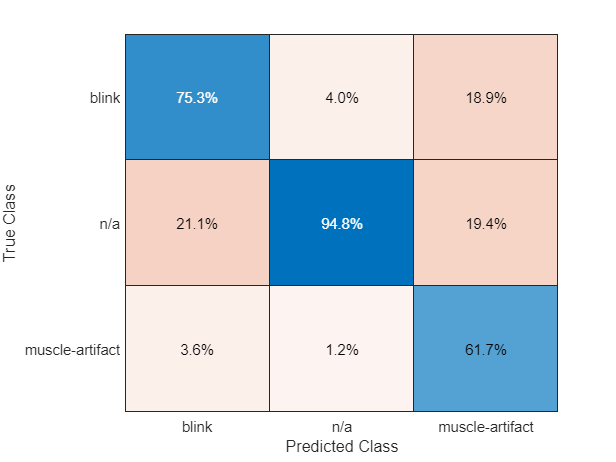

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');